%% 契比雪夫Ⅰ型IIR数字高通滤波器设计
% 要求0≤f_s≤40Hz，δ_s≥60dB，f_p>150Hz，δ_p≤1dB，采样频率F_T=20×f_p
% 绘制滤波器幅频特性曲线和零极点图

fs = 40;       % 阻带截止频率(Hz)
fp = 150;      % 通带起始频率(Hz)  
ds = 60;       % 阻带衰减最小值(dB)
dp = 1;        % 通带波纹最大值(dB)
fT = 20*fp;    % 采样频率(Hz)
T = 1/fT;      % 采样周期(s)

% 采用双线性变换法设计契比雪夫Ⅰ型高通滤波器
% 预畸变校正
Wp = 2*pi*fp*T;    % 数字通带角频率
Ws = 2*pi*fs*T;    % 数字阻带角频率
wp_prewarped = (2/T) * tan(Wp/2);  % 预畸变通带频率
ws_prewarped = (2/T) * tan(Ws/2);  % 预畸变阻带频率

% 设计模拟契比雪夫Ⅰ型高通滤波器
[N, wc] = cheb1ord(wp_prewarped, ws_prewarped, dp, ds, 's');
[num_analog, den_analog] = cheby1(N, dp, wc, 'high', 's');

% 双线性变换
[numd, dend] = bilinear(num_analog, den_analog, fT);

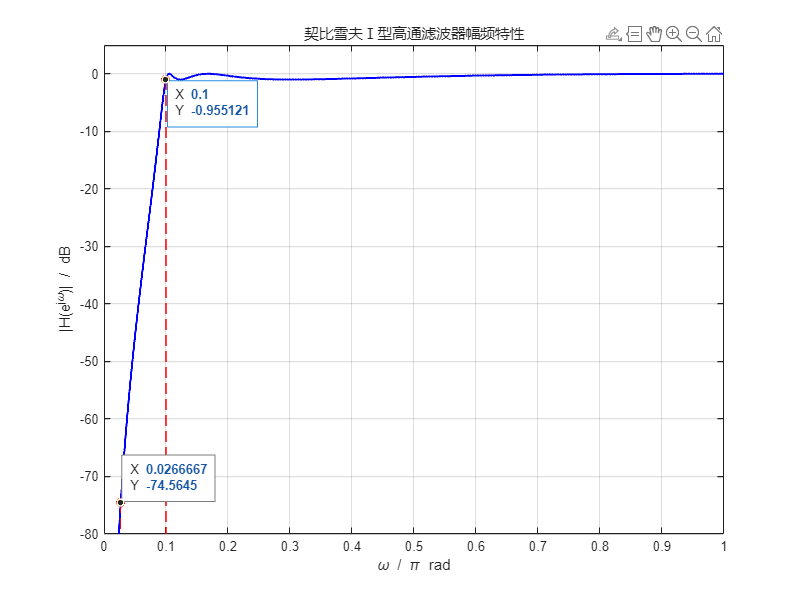


%% 图形1: 幅频特性曲线
figure('Position', [100, 100, 800, 600]);

w = linspace(0, pi, 1000);
H = freqz(numd, dend, w);
H_dB = 20*log10(abs(H));

plot(w/pi, H_dB, 'b-', 'LineWidth', 1.5);
grid on;
title('契比雪夫Ⅰ型高通滤波器幅频特性');
xlabel('\omega / \pi rad');
ylabel('|H(e^{j\omega})| / dB');
axis([0, 1, -80, 5]);

% 标记数字滤波器的通带和阻带边界
wp_index = find(w >= Wp, 1);
ws_index = find(w >= Ws, 1);
wp_magnitude = H_dB(wp_index);
ws_magnitude = H_dB(ws_index);
hold on;

plot([Wp/pi, Wp/pi], [wp_magnitude, -300], 'r--', 'LineWidth', 1);
plot([Ws/pi, Ws/pi], [ws_magnitude, -300], 'r--', 'LineWidth', 1);
plot(Wp/pi, wp_magnitude, 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'red');
plot(Ws/pi, ws_magnitude, 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'red');

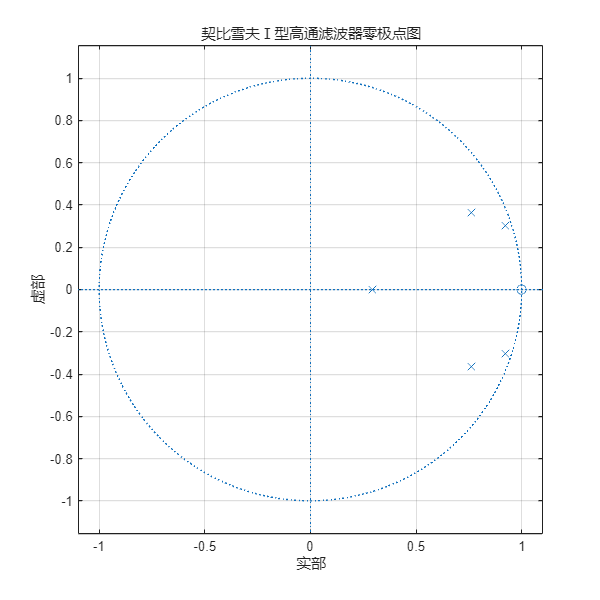

%% 图形2: 零极点图
figure('Position', [200, 100, 600, 600]);

subplot(1,1,1);
zplane(numd, dend);
title('契比雪夫Ⅰ型高通滤波器零极点图');
grid on;